# Cell Coloring Models via DLA

Let us first do this for 2500 steps.

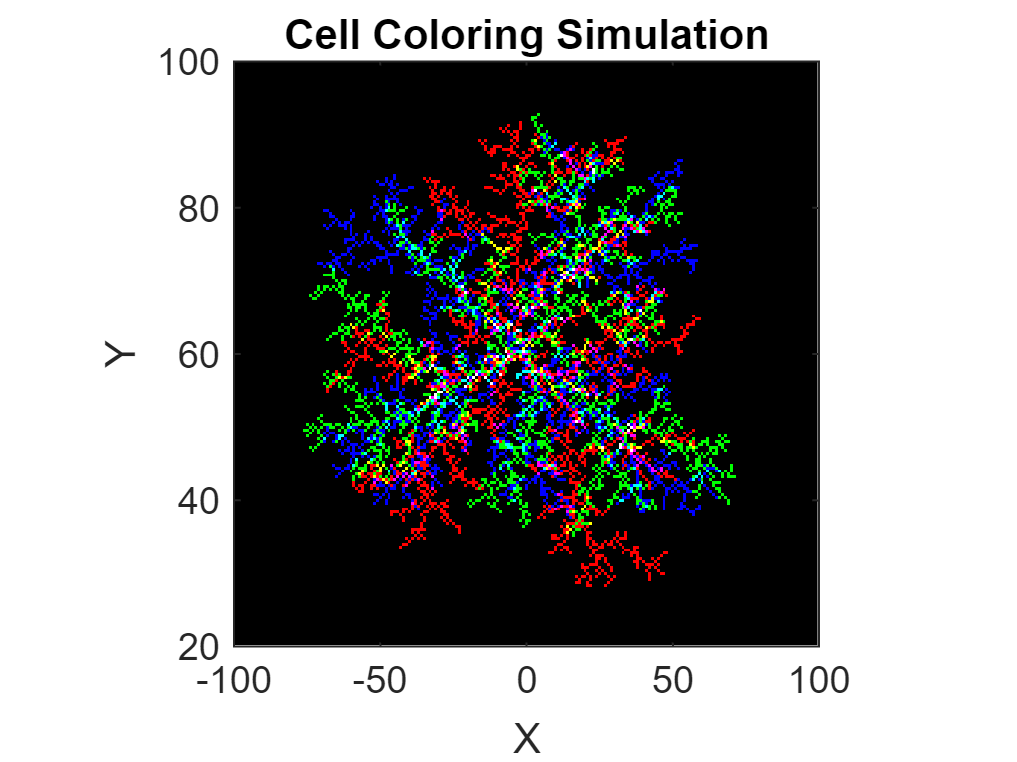

tic
DLA_CellColoringParallelized(200, 2500, 10)

toc

Elapsed time is 256.512277 seconds.


Here we define the function to perform the parallelized DLA algorithm.

function DLA_CellColoringParallelized(gridSize, numParticles, stickDistance)
    % Initialize grid
    grid = zeros(gridSize);

    % Place seed particle at the center of the grid
    startX = gridSize/2;
    startY = gridSize/2;
    grid(startX, startY) = 1;

    % Define colors for particles
    colors = [1 0 0; 0 0 1; 0 1 0];  % Red, Blue, Green

    % Initialize the combined grid for all colors
    combinedGrid = zeros(gridSize, gridSize, 3);

    % Define possible movement directions
    directions = [-1 0; 1 0; 0 -1; 0 1; -1 -1; -1 1; 1 -1; 1 1; -2 0; 2 0; 0 -2; 0 2];  % Up, Down, Left, Right, Diagonal directions, Extended diagonal directions

    % Main simulation loop
    for colorIndex = 1:size(colors, 1)
        color = colors(colorIndex, :);
        particleGrid = grid;
        
        for i = 1:numParticles
            % Generate a random position for the new particle
            x = randi([1, gridSize]);
            y = randi([1, gridSize]);

            % Check if the new particle sticks to the existing cluster
            while true
                % Check if any neighboring cells are occupied
                neighbors = particleGrid(max(1, x-1):min(gridSize, x+1), max(1, y-1):min(gridSize, y+1));
                if any(neighbors(:) == 1)
                    % Particle sticks to the cluster
                    particleGrid(x, y) = 1;
                    break;
                end

                % Move the particle randomly
                direction = directions(randi([1, numel(directions)/2]), :);
                newX = x + direction(1);
                newY = y + direction(2);

                % Check if the new position is within the grid boundaries
                if newX >= 1 && newX <= gridSize && newY >= 1 && newY <= gridSize
                    x = newX;
                    y = newY;
                end

                % Check if the particle is close enough to stick
                if particleGrid(x, y) == 1
                    % Particle sticks to the cluster
                    particleGrid(x, y) = 1;
                    break;
                end
            end
        end

        % Store the particle grid for the current color
        combinedGrid(:,:,colorIndex) = particleGrid;
    end

    % Display the final grid with all colors
    figure;
    colormap([1 1 1; colors]);
    imagesc((-gridSize/2:gridSize/2-1), (-gridSize/2:gridSize/2-1), combinedGrid);
    axis equal;
    axis([-gridSize/2 gridSize/2 -gridSize/2 gridSize/2]);  % Set axis limits
    title('Cell Coloring Simulation');
    xlabel('X');
    ylabel('Y');

    % Reverse the y-axis tick labels
    yticks = get(gca, 'YTick');
    yticklabels = arrayfun(@(x) sprintf('%d', -x), yticks, 'UniformOutput', false);
    set(gca, 'YTickLabel', yticklabels);

end